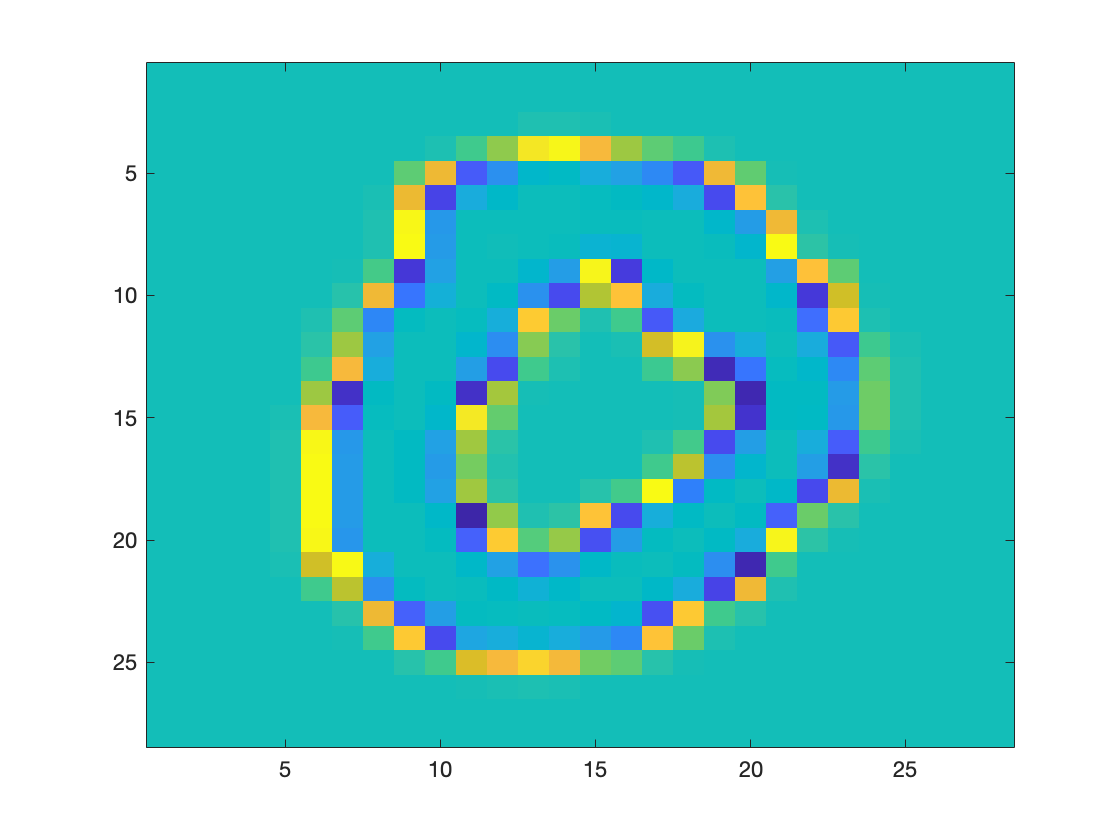

clear all; close all; clc
load('images.mat'); load('labels.mat');
IMAGES=images;
LABELS=labels;
clear 'images'
clear 'labels'
im=permute(IMAGES, [2,3,1]);
im=double(im);
%figure 1
figure(1)
imagesc(im(:,:,1));

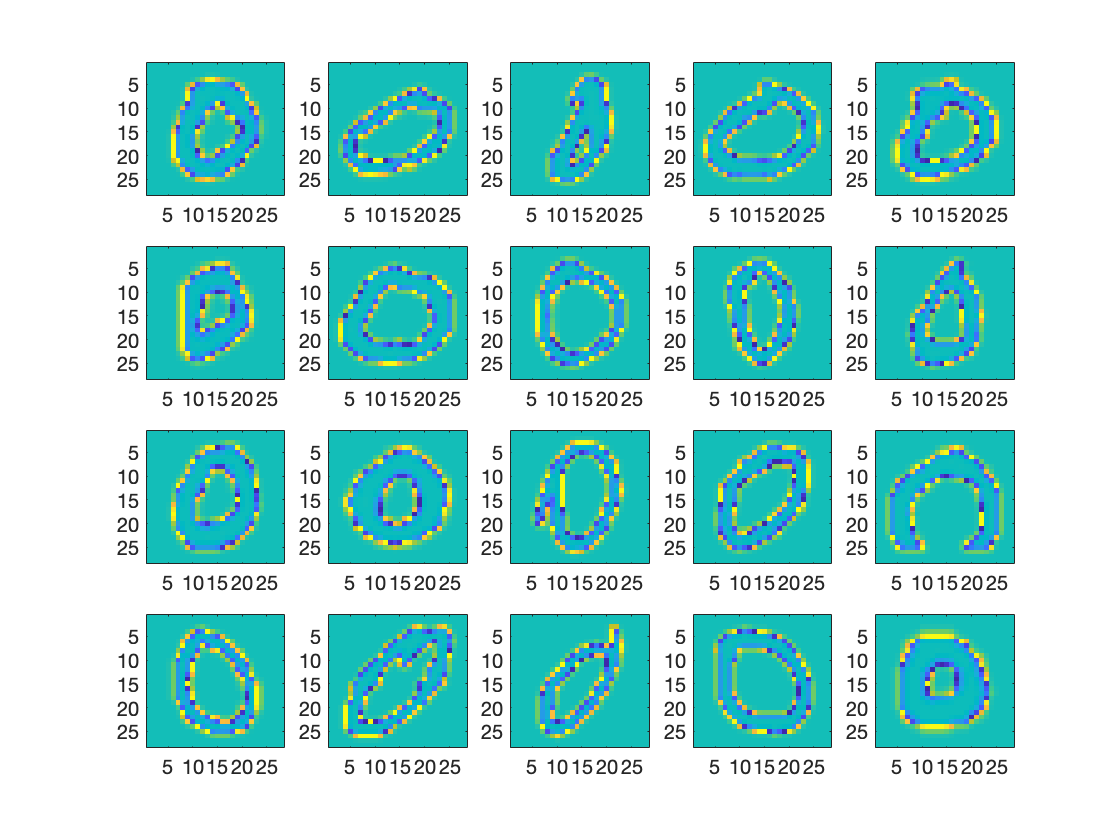

%first 1000 digits
%im1000=im(:,:,1:1000);
%figure 2 find digits
label0=find(LABELS==0);
label1=find(LABELS==1);
label2=find(LABELS==2);
label3=find(LABELS==3);
label4=find(LABELS==4);
label5=find(LABELS==5);
label6=find(LABELS==6);
label7=find(LABELS==7);
label8=find(LABELS==8);
label9=find(LABELS==9);

LABELSlowercase={'a','b','c','d','e','f','g','h','i','j'...
             'k','l','m','n','o','p','q','r','s','t'...
             'u','v','w','x','y','z'};
LABELScapital={'A','B','C','D','E','F','G','H','I','J','K','L','M'...
              'N','O','P','Q','R','S','T','U','V','W','X','Y','Z'};
%for 0
figure(2)
for ii=1:20
    subplot(4,5,ii), imagesc(im(:,:,label0(ii))) 
end

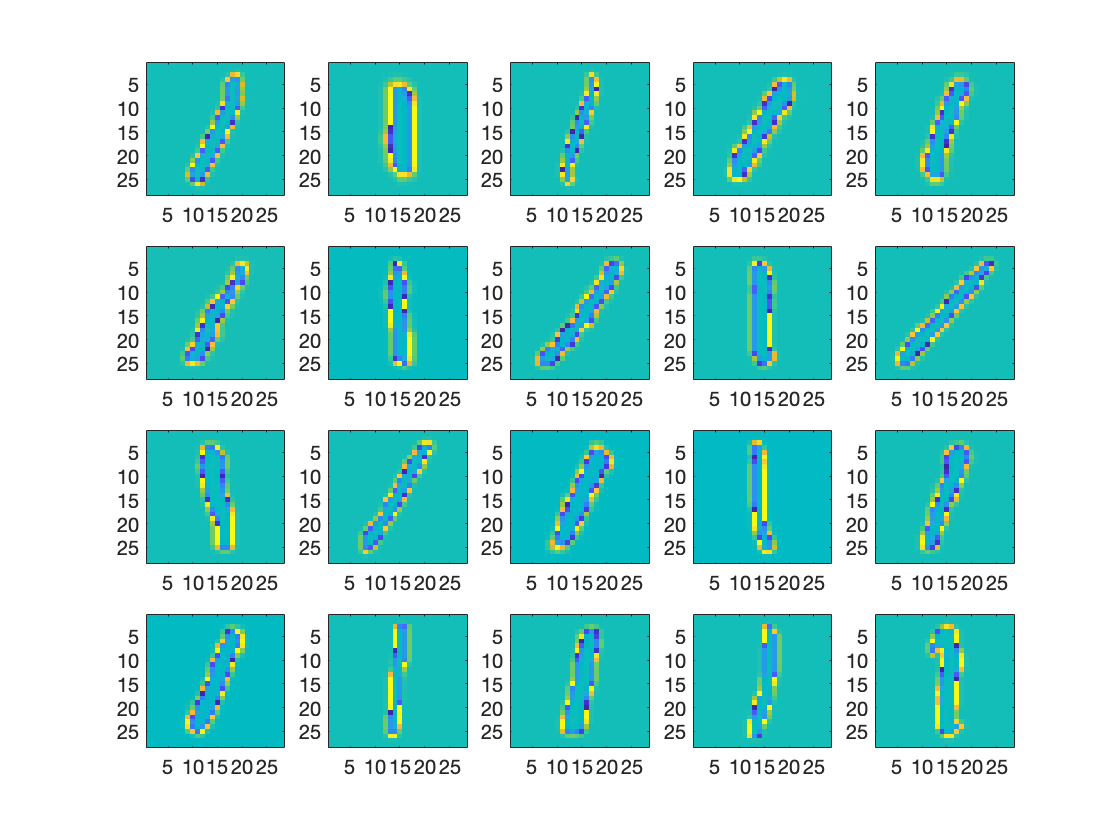

%for 1
figure(3)
for ii=1:20
    subplot(4,5,ii), imagesc(im(:,:,label1(ii))) 
end

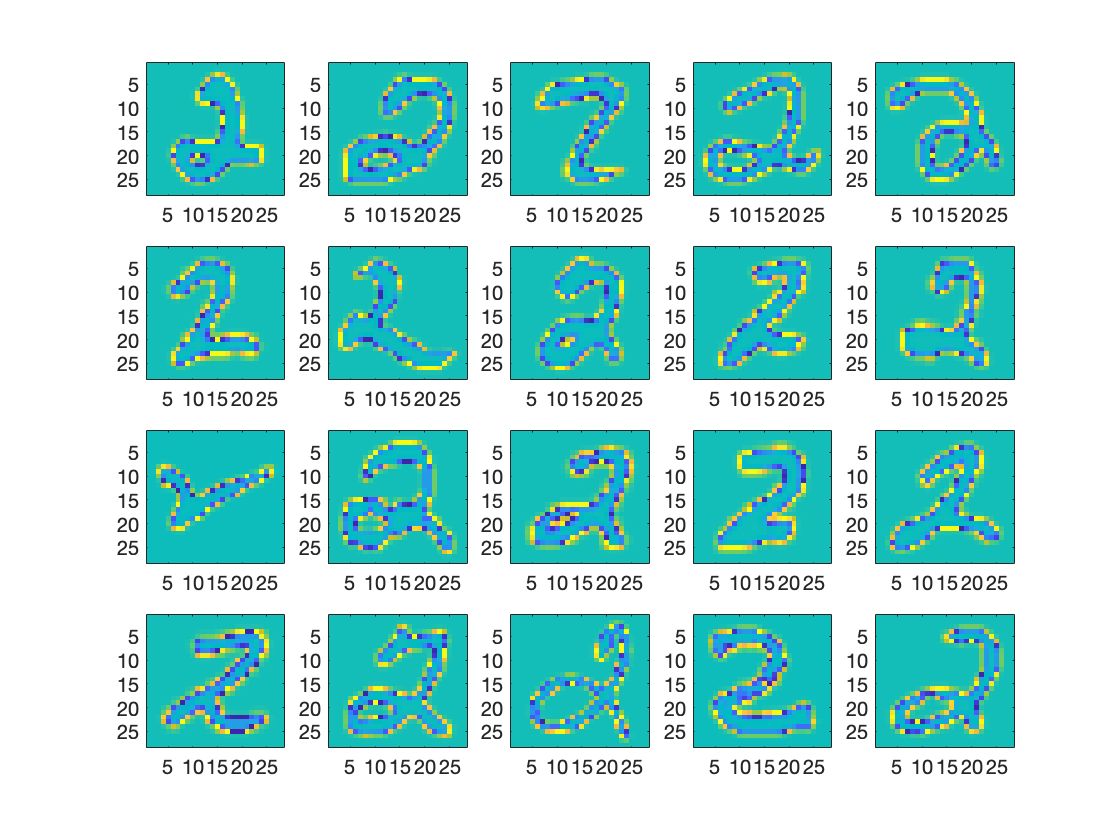

%for 2
figure(4)
for ii=1:20
    subplot(4,5,ii), imagesc(im(:,:,label2(ii))) 
end

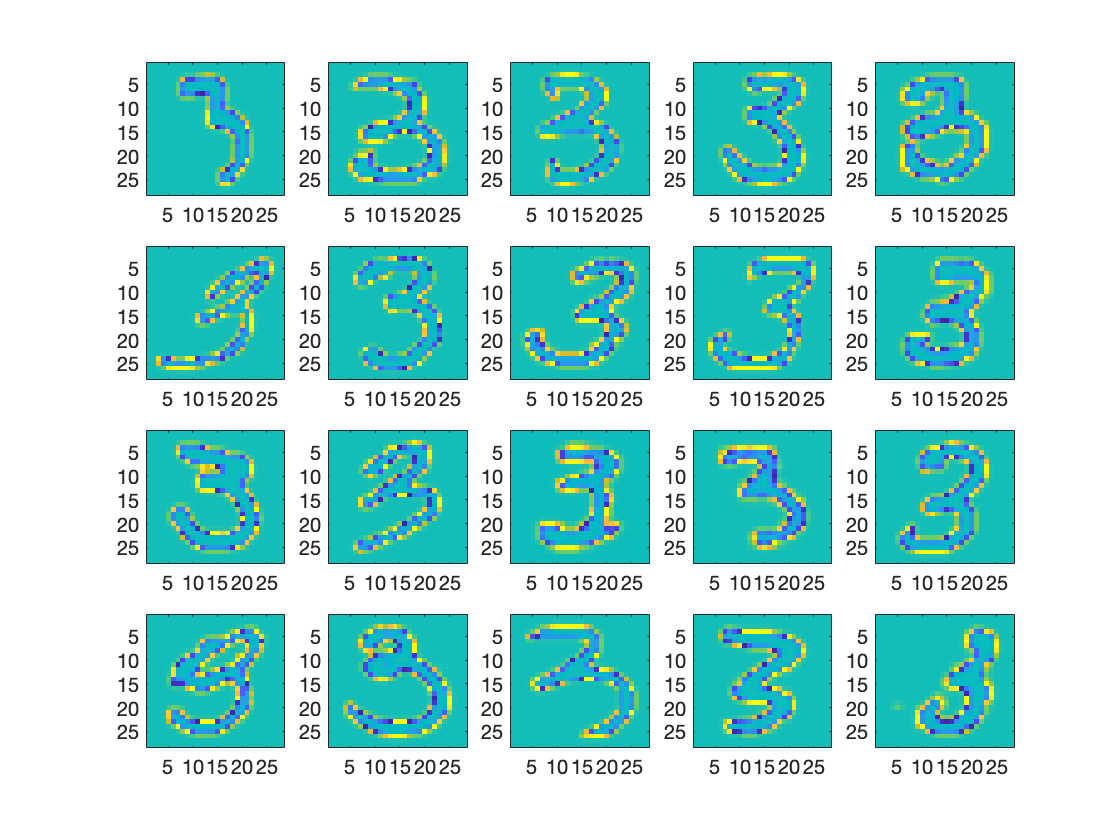

%for 3
figure(5)
for ii=1:20
    subplot(4,5,ii), imagesc(im(:,:,label3(ii))) 
end

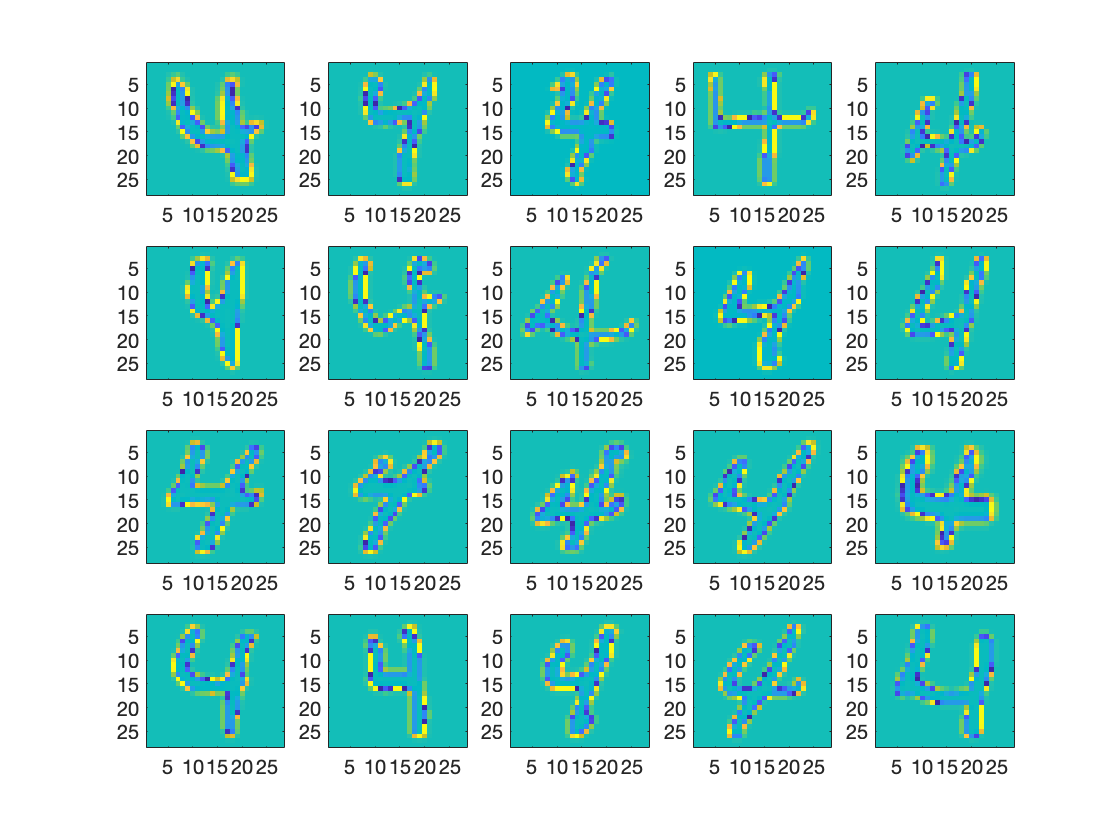

%for 4
figure(6)
for ii=1:20
    subplot(4,5,ii), imagesc(im(:,:,label4(ii))) 
end

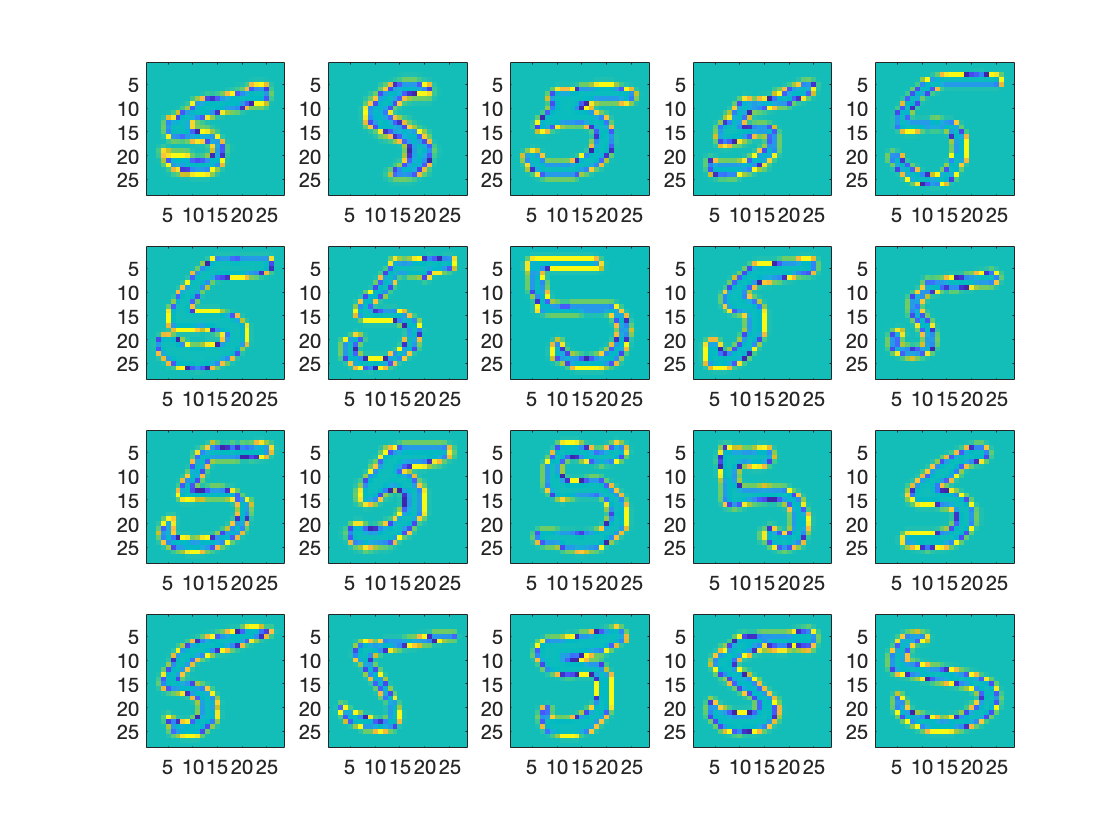

%for 5
figure(7)
for ii=1:20
    subplot(4,5,ii), imagesc(im(:,:,label5(ii))) 
end

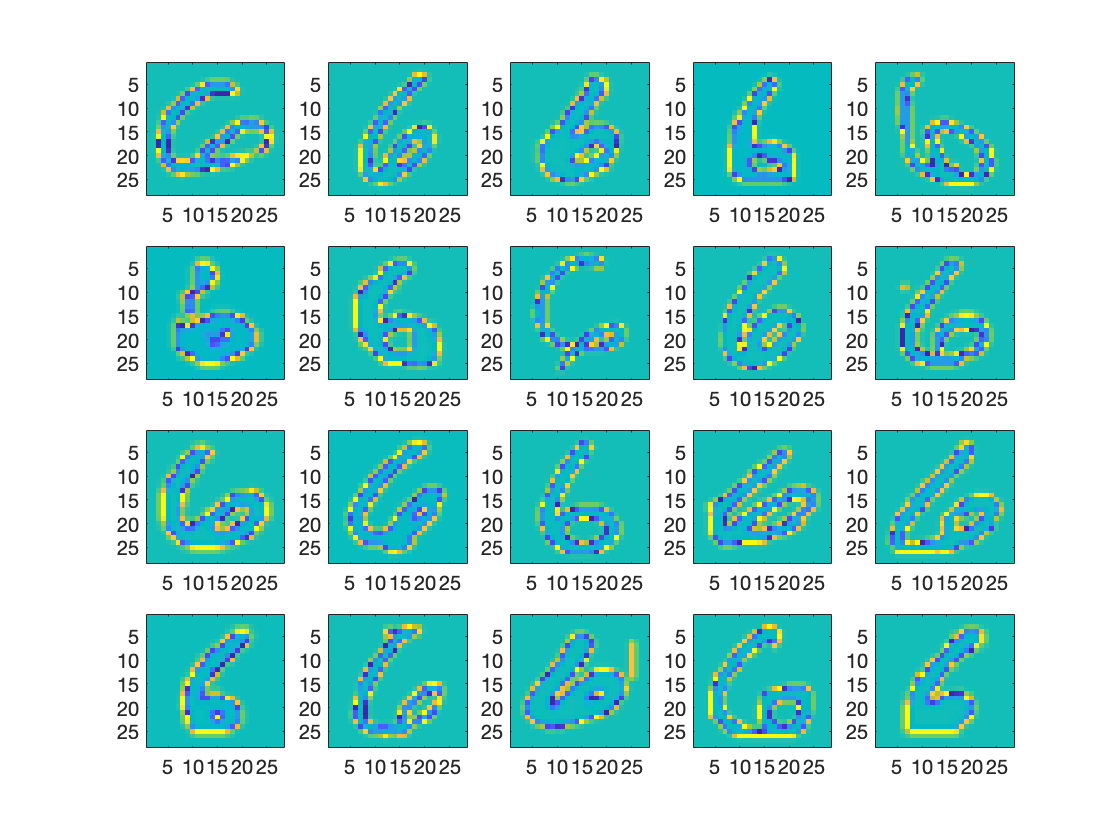

%for 6
figure(8)
for ii=1:20
    subplot(4,5,ii), imagesc(im(:,:,label6(ii))) 
end

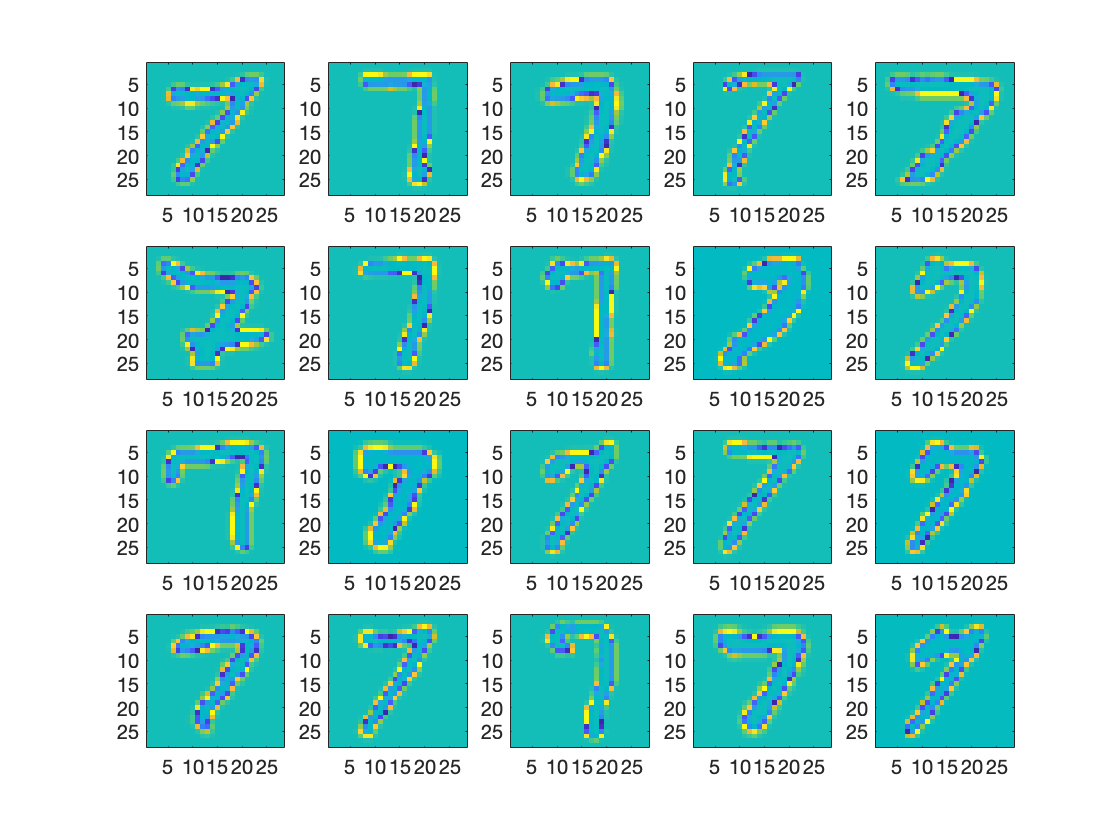

%for 7
figure(9)
for ii=1:20
    subplot(4,5,ii), imagesc(im(:,:,label7(ii))) 
end

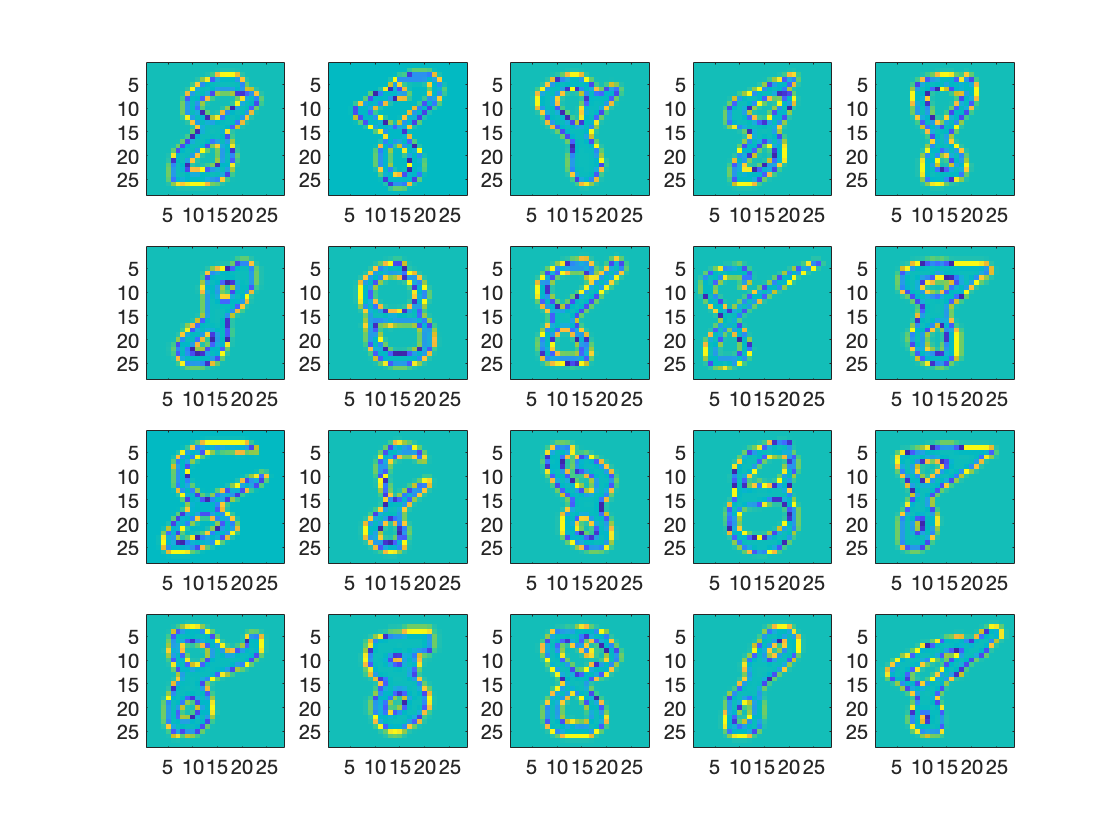

%for 8
figure(10)
for ii=1:20
    subplot(4,5,ii), imagesc(im(:,:,label8(ii))) 
end

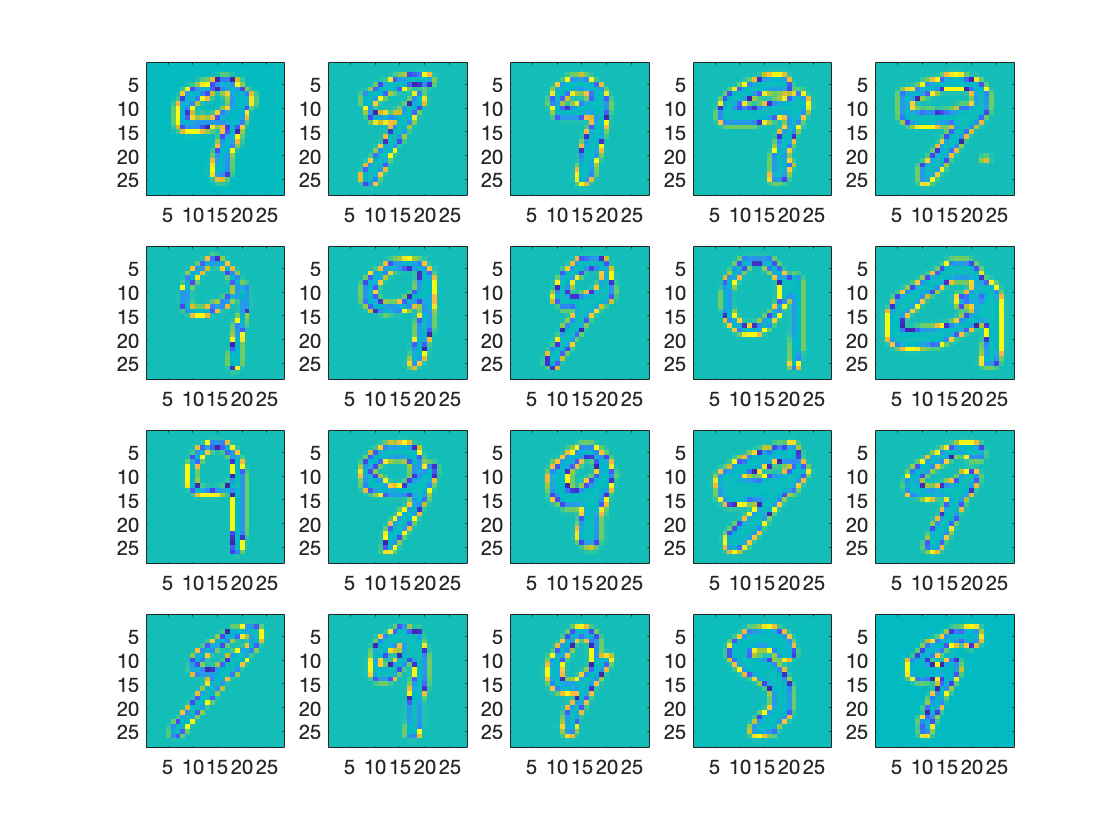

%for 9
figure(11)
for ii=1:20
    subplot(4,5,ii), imagesc(im(:,:,label9(ii))) 
end

%for digit



%for capital
LABELScapital=char(LABELScapital);
for ii=1:26
    temp=find(LABELS==ii+9);
    eval(['label',LABELScapital(ii),'=','temp',';']);
end


%for lowercase 
LABELSlowercase=char(LABELSlowercase);
for ii=1:26
    temp=find(LABELS==ii+35);
    eval(['label',LABELSlowercase(ii),'=','temp',';']);
end


rim=zeros(784,length(im));
for ii=1:length(im)
rim(:,ii)=reshape(im(:,:,ii),[],1);%reshape images data
end

